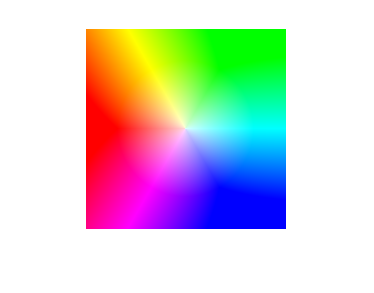

s=200;
a=zeros(s,s,3);
b=zeros(s,s);
for i=1:s
    for j=1:s
        Dx=i-s/2;
        Dy=j-s/2;
        r=sqrt(Dx^2+Dy^2);
        theta=atan2d(Dx,Dy)+180;
        b(i,j)=theta;
        a(i,j,1)=theta/360;
        a(i,j,2)=0.15+(r/(s/2.5));
        a(i,j,3)=1;
    end
end
b=hsv2rgb(a);
imshow(b)

imwrite(b,"imgfile1200_colors.png");